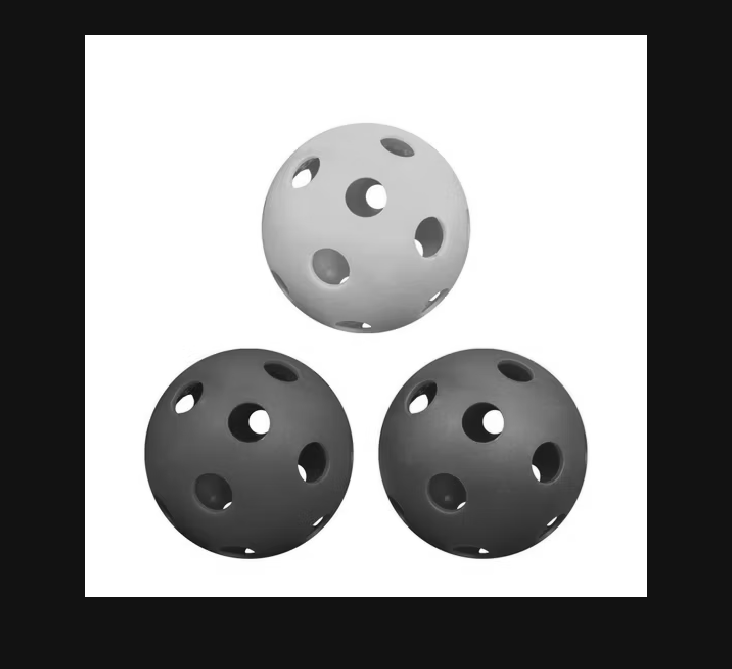

clear all;
close all;

img = imread('demo1.png');
gray = im2gray(img);
imshow(gray);

Find centers and radius of circles

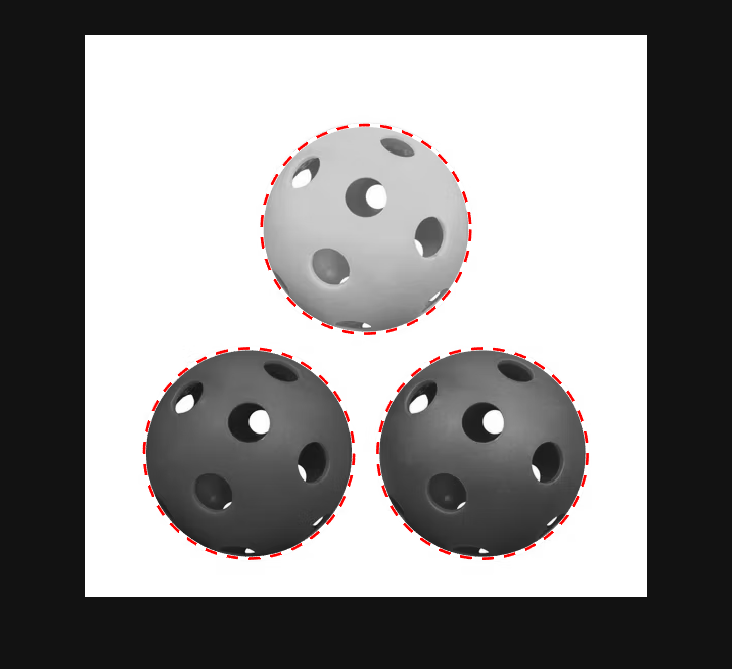

Rmin = 60;
Rmax = 200;
% Find bright objects
[centersBright, radiiBright] = imfindcircles(img, [Rmin Rmax], 'ObjectPolarity', 'bright');
% Find dark objects
[centersDark, radiiDark] = imfindcircles(img, [Rmin Rmax], 'ObjectPolarity', 'dark', 'Sensitivity', 0.91);
viscircles(centersBright, radiiBright, 'EdgeColor', 'b');
viscircles(centersDark, radiiDark, 'EdgeColor', 'r', 'LineStyle', '--');